# KCC Kernel Derivation

This notebook will be used for the derivation of the kernel cross correlator and some of its other variations that lead into it. There is also a brief section of the training of the KCC and what takes the KCF into the KCC domain via use of objective training mapping. The final equation will then become:


$$\hat{R}_{xy} = K_t(\hat{X}, \hat{X}) \odot  \hat{H}(y)
$$


                                                                                                                                                where:


$$\hat{H}(y) = \hat{G}(z_n) \odot K_t(\hat{Y}, \hat{Y})$$


## Initial Setup

% --Setup
    clear; clc; format compact; close all; 
    cd("/home/samkramer/Desktop/Engineering/Chirp Detection Algorithm/MAT Notebooks")

% --Declare Basic Signal

    % --Signal Parameters
        T = 1;              % Signal Period T (s)
        fs = 10000;         % Sample Rate (Hz)
        t = 0:1/fs:T;
        f = 10*2*pi;        % Frequency (Hz)

    % --Create signal
        amplitude = 0.25;
        envelope = amplitude.* sin(pi*t);
        ref_signal = envelope .* sin(f*t);

% --Creating sample signal
    t1 = 0:1/fs:5;
    amplitude = 1;
    envelope = amplitude.* sin(pi*t1);
    signal = envelope .* sin(f*t1);
    noisy_signal = randi(100,1,length(t1))./400 + signal;
    signal = noisy_signal - mean(noisy_signal);

% --Zero pad signals to make same length
    diff = length(signal) - length(ref_signal);
    pad = zeros([1, diff]);
    ref_signal_long = [ref_signal, pad];

## Derivation

### Correlation Derivation

Given that we have the following definition of the non-normalized cross correlation function xcf:


$$\hat{R}_{xy} = \hat{X} \odot \hat{Y}^*$$


Where the $^*$ denotes the complex conjugate of the vector in the fourier domain.

% --Taking fft of both signals
    xf = fft(signal);
    yf = fft(ref_signal_long);
    
% --Taking correlation
    Rxyf = xf .* conj(yf);
    Rxy = ifft(Rxyf);               % FINAL CORRELATION

We can then transform the signals by taking the kernel of both and calling this a kernel covarience function:


$$\hat{R}_{xy} = K(\hat{X}, \hat{X}) \odot K(\hat{Y}, \hat{Y})^*$$


Where $K(x,x)$ is the kernel transformation of the dataset x.

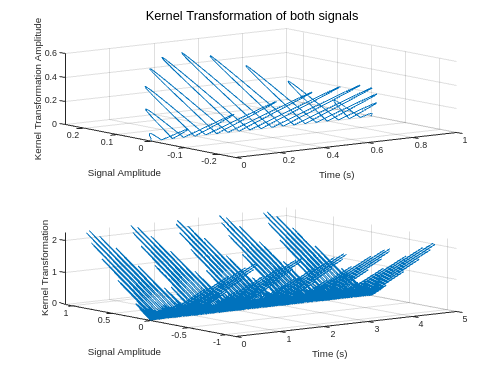

% --Taking the Kernel Kernel
    Kxx = abs(signal + signal);                             % Mathematically the same because using L-abs kernel
    Kyy = Labs_kernel(ref_signal_long, ref_signal_long);

% --Plot kernel functions
    figure()
    subplot(2,1,1)
    plot3(t1, ref_signal_long, Kyy)
        grid on 
        xlabel("Time (s)")
        ylabel("Signal Amplitude")
        zlabel("Kernel Transformation Amplitude")
        xlim([0 1])
    subplot(2,1,2)
    plot3(t1, signal, Kxx)
        hold on
        grid on
        xlabel("Time (s)")
        ylabel("Signal Amplitude")
        zlabel("Kernel Transformation")
        sgtitle("Kernel Transformation of both signals")

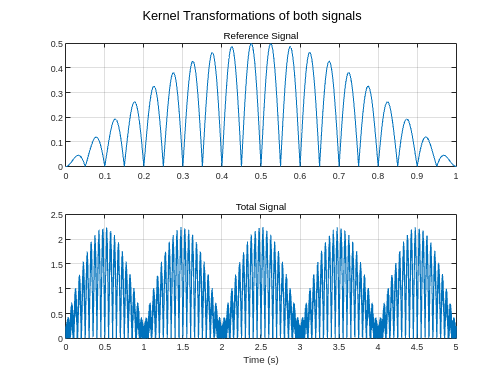

% --Plot Kernel Transformations
    figure()
    subplot(2,1,1)
    plot(t1, Kyy)
        hold on
        grid on
        subtitle("Reference Signal")
        xlim([0 1])
    subplot(2,1,2)
    plot(t1, Kxx)
        grid on
        subtitle("Total Signal")
        sgtitle("Kernel Transformations of both signals")
        xlabel("Time (s)")

Now if we were to take the correlation output of this we would essentially be doing the following mathematical equation:


$$\hat{R}_xy = |\hat{X} - \hat{X}^*| \odot |\hat{Y} - \hat{Y}^*|^*$$


is equivalent to our follwing notation:


$$\hat{R}_{xy} = K_t(\hat{X}, \hat{X}) \odot K_t(\hat{Y}, \hat{Y})$$


where the $K_t$ is our transformation kernel function $\phi(x,y)$ selected for our problem. In the above formulation we are using the L-Abs kernel. Note that this is within the frequency domain in order to speed up the process, therefore the kernel functions must be written in their frequency domain equivalents. 

To get out of the frequency domain we can then take the inverse fourier transform to get $R_{xy}$ in the temporal domain.  This yields the Kernel cross function that does not implement the training of the data needed to non-linearly describe the KCC that we are interested in exploring. KCF looks like the following:

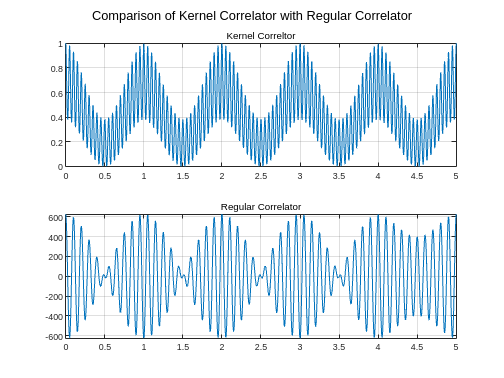

% --Finding the Correlation
    kxxf = fft(Kxx);
    kyyf = fft(Kyy);
    Rxyk = ifft(kxxf.*conj(kyyf));
    Rxyk = Rxyk - min(Rxyk);
    Rxyk = Rxyk ./ max(Rxyk);

% --Plot
    figure()
    subplot(2,1,1)
    plot(t1, Rxyk)
        hold on
        grid on
        subtitle("Kernel Correltor")
    subplot(2,1,2)
    plot(t1, Rxy)
        hold on
        grid on
        subtitle("Regular Correlator")
        sgtitle("Comparison of Kernel Correlator with Regular Correlator")

One more key step in our formulation of the KCC is the implementation of the training mapping into our math. To do this we must redefine the reference term that we are going to be checking our signal with to be called $H(y)$ which contains our training. Right now all we have is the following:


$$\hat{H}(y) = K_t(\hat{Y}, \hat{Y})$$


Training can be seen as the convolution of the kernel transformation onto a particular training set that has been selected prior to use. In this case because we are in the frequency domain, we may multiply the sets together to train our data. $\hat{H}(y) = \hat{G}(z_n) \odot K_t(\hat{Y}, \hat{Y})$ with $n$ training vector sets $z$ within our training set $G(z)$. Those take the following: $G(z_ n) = [z_1, z_2, z_3, ... z_n]$where the number of data points in the training set must be equalivalent to the number of points in the reference signal kernel transformation, and the number of points in the data set $x$. So now our formulation becomes:


$$\hat{R}_{xy} = K_t(\hat{X}, \hat{X}) \odot  \hat{H}(y)
$$


                                                                                                                                                where :


$$\hat{H}(y) = \hat{G}(z_n) \odot K_t(\hat{Y}, \hat{Y})$$


The training sets must also be within the fourier domain as well. This next section will now look at three different training sets to discuss their differences and how they affect the output to the system. One will be a simple impulse trainer like before which is ones in all frequencies, the second will be the triangle trainer, and the third will be the correlation of the two signals $\hat{R}_{xy}$. The purpose is to show the differences in the training and the how they change the output data. 

### Training Exploration

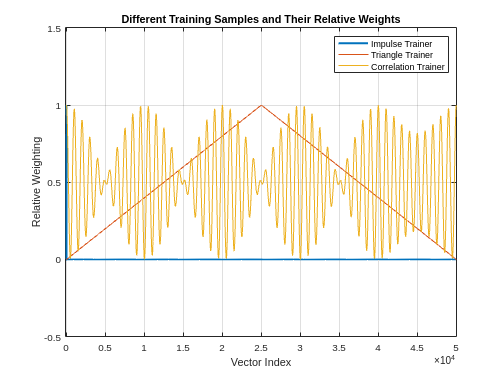

% --Define Impulse trainer
    g_hat_impulse = ones(1,length(ref_signal_long));        % This is the trainer within the fourier domain
    g_impulse = ifft(g_hat_impulse);

% --Triangle Trainer
    x = 0:length(ref_signal_long)/2;
    x = [x flip(x)];
    x = x(1:end - 1);
    g = 1/max(x) .* x;
    g_hat_tri = fft(g);

% --Correlation Trainer
    g_hat_corr = Rxyf;
    g_corr = ifft(g_hat_corr);
    g_corr = (g_corr - min(g_corr));
    g_corr = g_corr ./(max(g_corr));

% --THEREFORE OUR TRAINERS IN THE FREQ DOMAIN:
    g_hat_corr;         % Correlation Trainer
    g_hat_tri;          % Triangle Wave Trainer
    g_hat_impulse;      % Impulse Trainer

% --Plotting
    figure()
    plot(g_impulse, "linewidth", 2)
        hold on
        grid on
    plot(g)
    plot(g_corr)
    xlim([-100 50001])
    ylim([-0.5 1.5])
    legend("Impulse Trainer", "Triangle Trainer", "Correlation Trainer")
    title("Different Training Samples and Their Relative Weights")
    ylabel("Relative Weighting")
    xlabel("Vector Index")

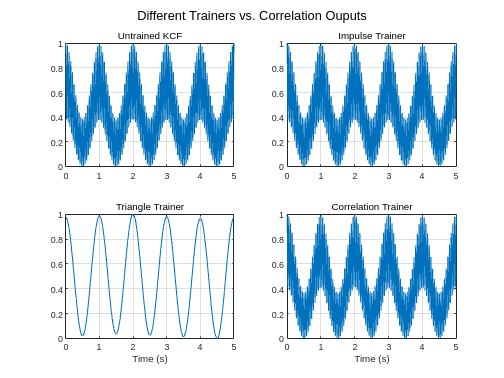

% --Exploring using the Impulse trainer
    Rxyk_impulse = ifft(kxxf .* conj(g_hat_impulse .* kyyf));
    Rxyk_impulse = Rxyk_impulse - min(Rxyk_impulse);
    Rxyk_impulse = Rxyk_impulse ./ max(Rxyk_impulse);

% --Exploring using Triangular trainer
    Rxyk_triangle = -1 .* ifft(kxxf .* conj(g_hat_tri .* kyyf));
    Rxyk_triangle = Rxyk_triangle - min(Rxyk_triangle);
    Rxyk_triangle = Rxyk_triangle ./ max(Rxyk_triangle);

% --Exploring using Correlation Trainer
    Rxyk_correlation = abs(ifft(kxxf .* g_corr.* conj(kyyf)));
    Rxyk_correlation = Rxyk_correlation - min(Rxyk_correlation);
    Rxyk_correlation = Rxyk_correlation ./ max(Rxyk_correlation);
    
% --Plotting output
    figure()
    subplot(2,2,1)
    plot(t1, Rxyk)
        hold on
        grid on
        subtitle("Untrained KCF")
    subplot(2,2,2)
    plot(t1, Rxyk_impulse)
        grid on
        subtitle("Impulse Trainer")
    subplot(2,2,3)
    plot(t1, Rxyk_triangle)
        hold on
        grid on
        xlabel("Time (s)")
        subtitle("Triangle Trainer")
    subplot(2,2,4)
    plot(t1, Rxyk_correlation)
        hold on
        grid on
        xlabel("Time (s)")
        subtitle("Correlation Trainer")
        sgtitle("Different Trainers vs. Correlation Ouputs")

                In the above figure, we can see that the untrained and the impulse functions remain relatively the same because of the mathematics of the impulse in the frequency domain: impulses contain infinite frequencies with equivalent energy, so therefore we are putting equivalent energy into our system without favoring or biasing the output. The triangle trainer will limit the frequencies to only low frequencies, acting almost as a smoothing function to the system. The idea of the correlation trainer was to implicitly tie in the traditional correlation function into the KCC however, it did not seem to have any effect on the system when in the time domain version, and had negative effect on the output when in the frequency domain, despite the peaks appearing in the same places. This may not be the best route, but could be useful later with another application of a kernel transformation.

                As we can see from the figure, the KCC will yield similar results from an impulse trained function and a correlation trained function, which brings up the question, do the training functions need to be kernelized to achieve the proper outputs? This will be discussed in the next section below where each of the trainers will be passed through a time domain kernel and then the correlation will be found in the frequency domain. However, this may not be useful as we may be squaring our system kernelizing our correlation trainer. This may not be as effective as I think it could be. Better to stick with other ideas. 

## Function Definitions

###    Linear Kernel

function kf = Labs_kernel(x, y) % Time domain defintion of kernel

    % --Find the kernel
        kf = abs(x + y);

end

###     Train Function

function correlator = train(data, sample, lambda, sigma)

    % --Early properties of the correlator
        correlator.sigma = sigma; 
        sample_fft = fft(sample);
        correlator.sample_fft = sample_fft;

    % --Calculating correlator 
        kernel = gaussian_kernel(sample_fft, sample_fft, sigma);
        kernel = kernel - mean(kernel);
        k_z = fft(kernel);

    % --Define training objective set (Uncomment sections)

        % --Triangular wave trainer
            x = 0:length(sample)/2;
            x = [x flip(x)];
            x = x(1:end - 1);
            g_hat = 1/max(x) .* x;
            g_hat_1 = abs(fft(g_hat));

        % --Correlation trainer 
            g_hat = xcorr(data, sample);
            g_hat = g_hat(1, round(length(g_hat)/2):end)./length(g_hat);
            g_hat_2 = abs(fft(g_hat));
            g_hat = g_hat_1 .* g_hat_2;          
        
    % --Define h_hat for our system
        % uses the following equation: h_hat = g_hat ./ k(sample)
        correlator.h_hat = g_hat./(k_z + lambda);
end

###     KXCorr Function

function output = kxcorr(data, sample)

        % --Test for column vector
            vec1 = iscolumn(data);
            vec2 = iscolumn(sample);

            if vec1 == 1
                data = data';
            elseif vec2 == 1
                sample = sample';
            end

        % --zero pad sample data to make same length
            if length(sample) < length(data)
                diff = length(data) - length(sample);
                pad = zeros([1, diff]);
                sample = [sample, pad];
            end

        % --Parameters
            lambda = 0.001;
            sigma = 0.2;

        % --Setup
            data_fft = fft(data);

        % --Train Model
            correlator = train(data, sample, lambda, sigma);

        % --Compute output
            kernel_fft = fft(gaussian_kernel(data_fft, correlator.sample_fft, sigma));
            output = abs(ifft(correlator.h_hat .* kernel_fft));
            output = output - mean(output);

end